# LFP Singnals Manual Cleanup 

## Set Parameters for Chronux Spectrogram

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product
K = 9; % the number of tapers, K = 2*TW - 1
params.tapers = [TW K];


## CT1

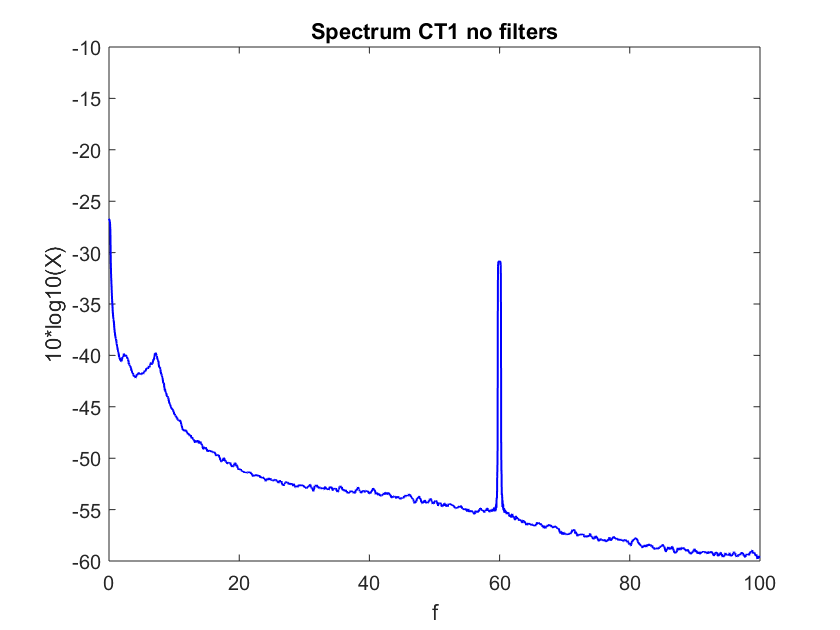

% Plot spectrum and spectrogram to look for artifacts
plot_spectrum_seg(CT1, 20, params); title('Spectrum CT1 no filters')

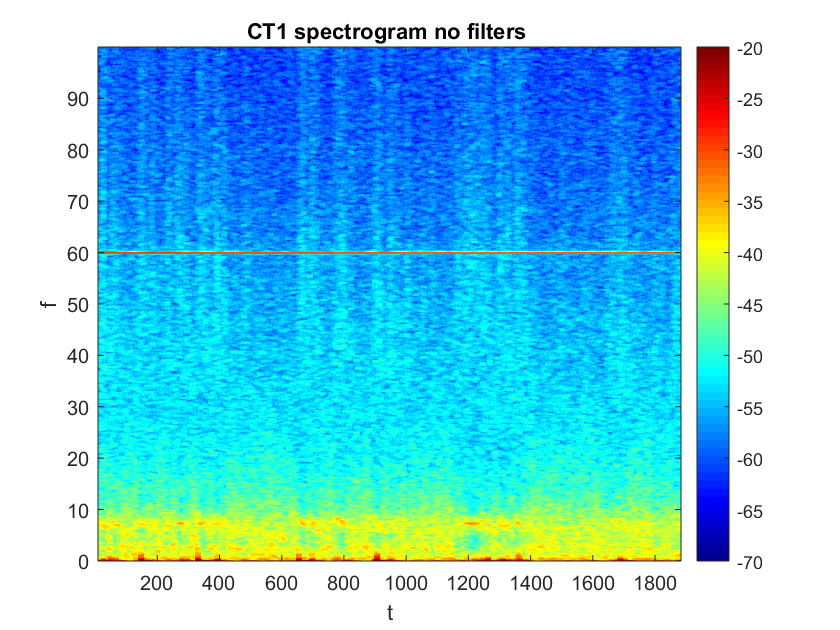


plot_spectrogram(CT1, [20 1], params) ; title('CT1 spectrogram no filters ');

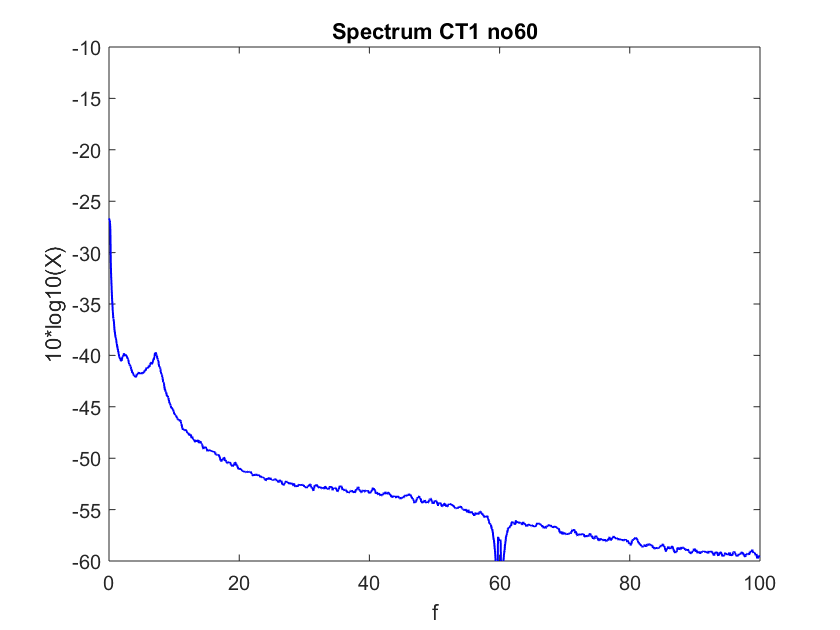


    % Only see 60 Hz noise, no artifacts

% Remove 60 Hz noise 
alpha = 0.995; 
band = 60;
F_CT1 = remove60(CT1, params.Fs, alpha, band);

% Plot with Filter
plot_spectrum_seg(F_CT1, 20, params); title('Spectrum CT1 no60');

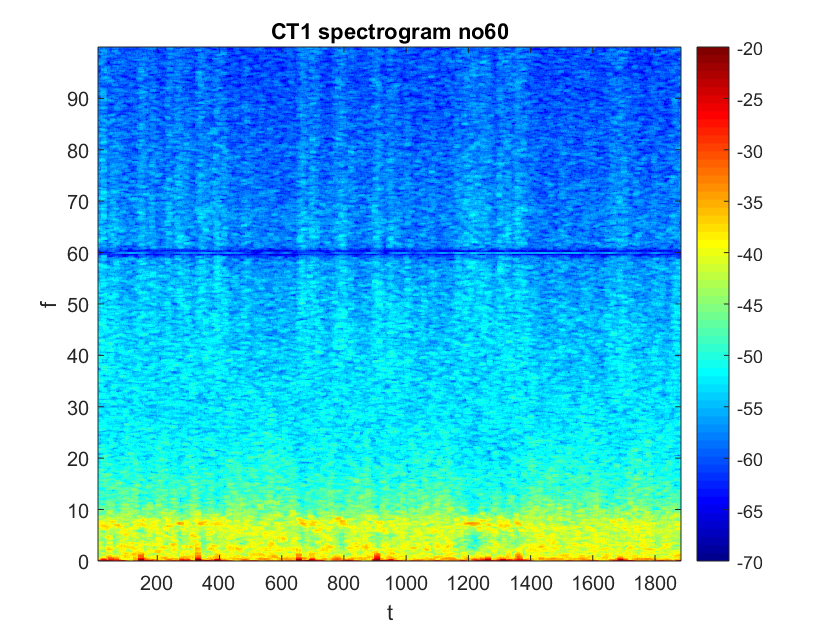


plot_spectrogram(F_CT1, [20 1], params) ; title('CT1 spectrogram no60');

## CT2

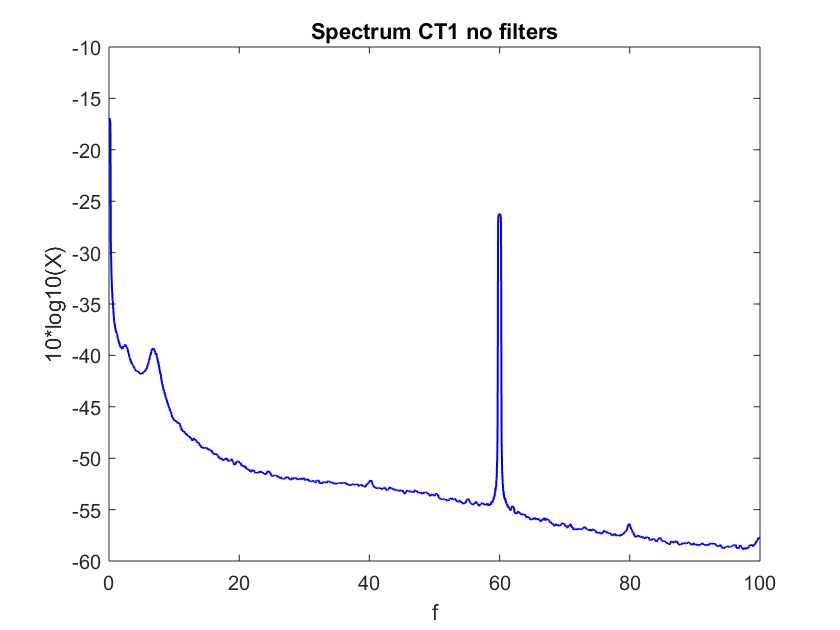

% Plot spectrum and spectrogram to look for artifacts
plot_spectrum_seg(CT2, 20, params); title('Spectrum CT2 no filters')

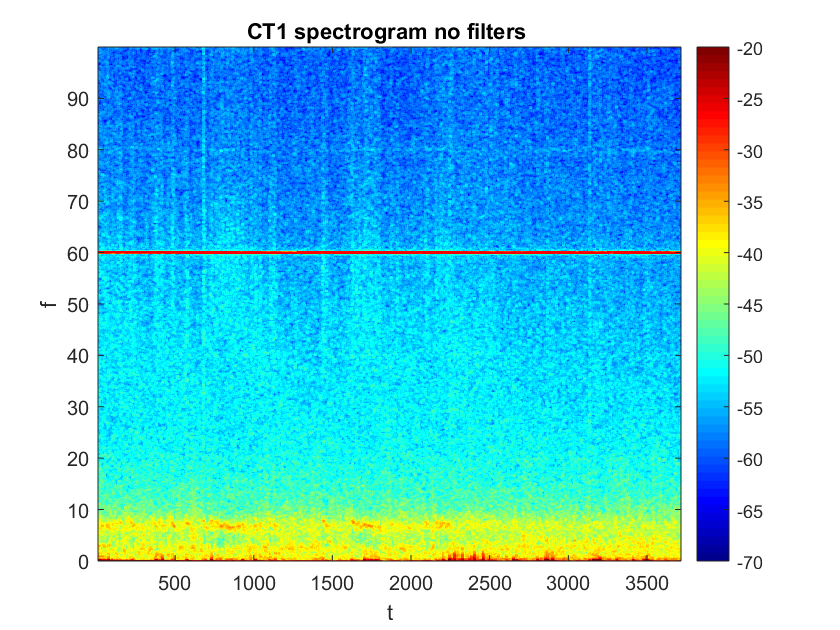


plot_spectrogram(CT2, [20 1], params) ; title('CT2 spectrogram no filters ');

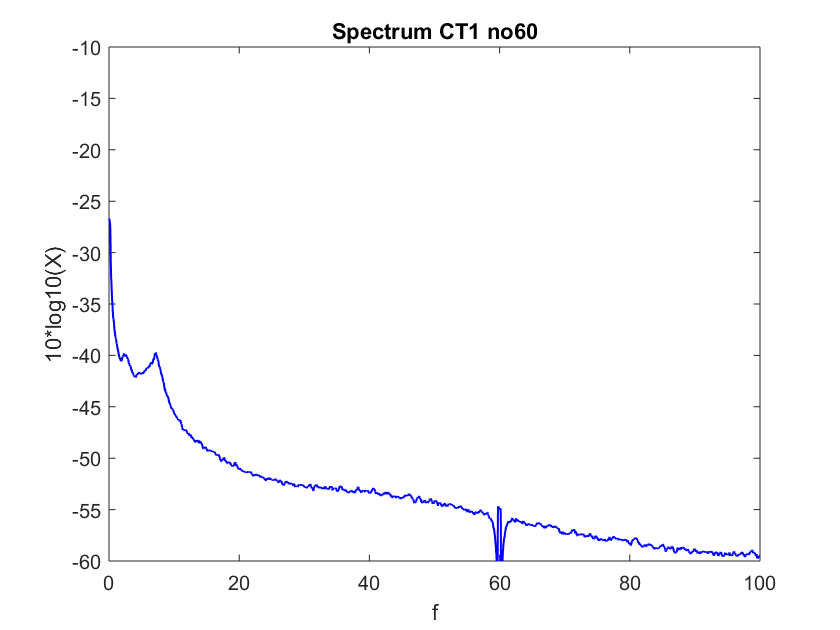


    % Only see 60 Hz noise, no artifacts

% Remove 60 Hz noise 
alpha = 0.9965; 
band = 60;
F_CT2 = remove60(CT1, params.Fs, alpha, band);

% Plot with Filter
plot_spectrum_seg(F_CT2, 20, params); title('Spectrum CT2 no60');

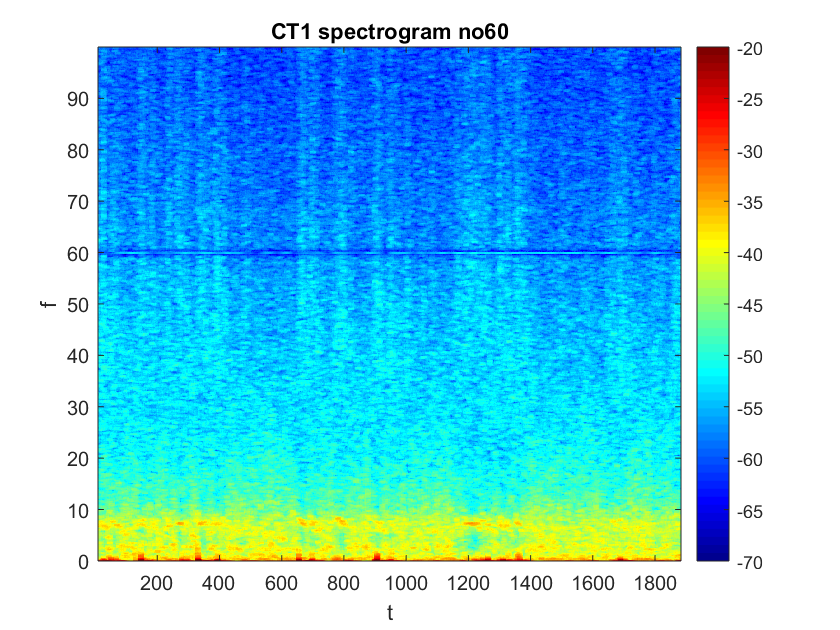


plot_spectrogram(F_CT2, [20 1], params) ; title('CT2 spectrogram no60');

## CT3

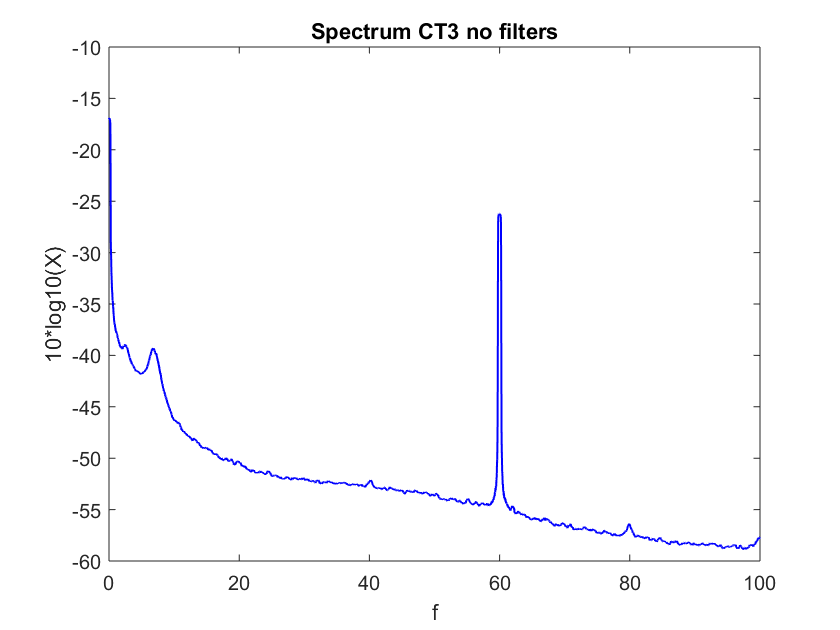

% Plot spectrum and spectrogram to look for artifacts
plot_spectrum_seg(CT2, 20, params); title('Spectrum CT3 no filters')

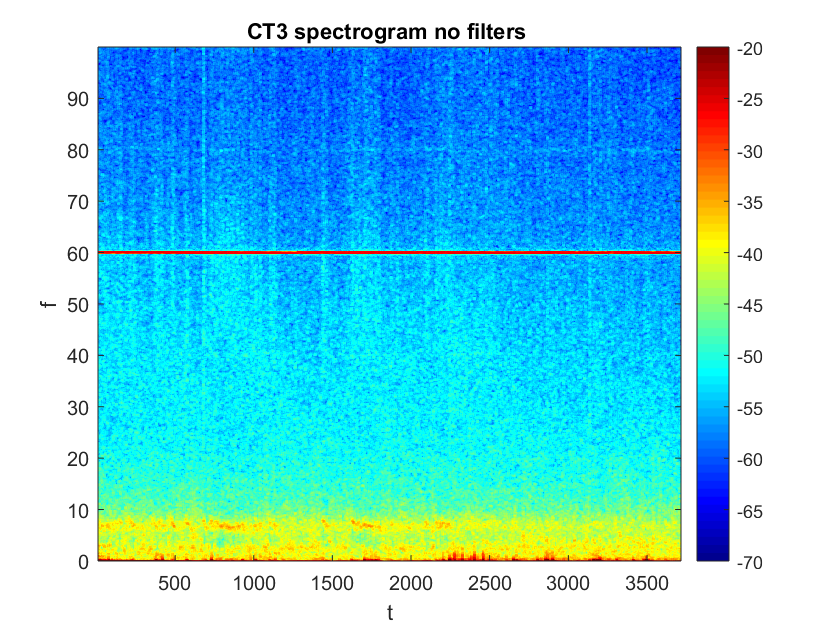


plot_spectrogram(CT2, [20 1], params) ; title('CT3 spectrogram no filters ');

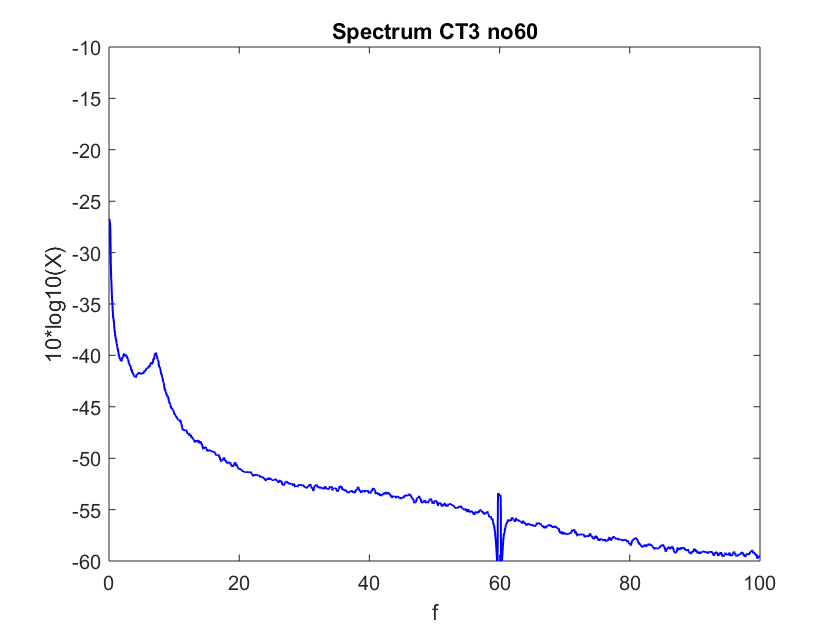


    % Only see 60 Hz noise, no artifacts

% Remove 60 Hz noise 
alpha = 0.997; 
band = 60;
F_CT2 = remove60(CT1, params.Fs, alpha, band);

% Plot with Filter
plot_spectrum_seg(F_CT2, 20, params); title('Spectrum CT3 no60');

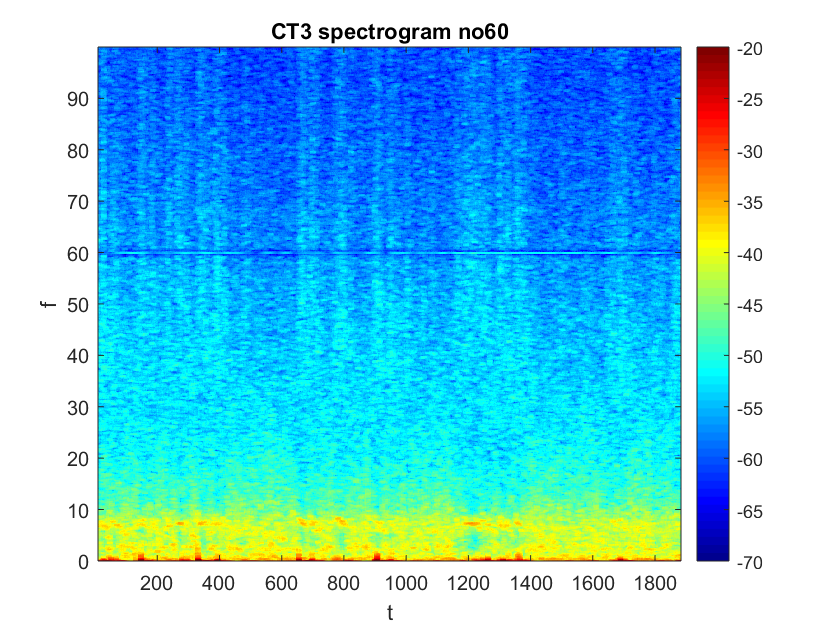


plot_spectrogram(F_CT2, [20 1], params) ; title('CT3 spectrogram no60');


%% Note: seems that filtering at 60 Hz removes the signal at 40 and 80 Hz 
%       - Will continue withough futher filtering for now

## CT4

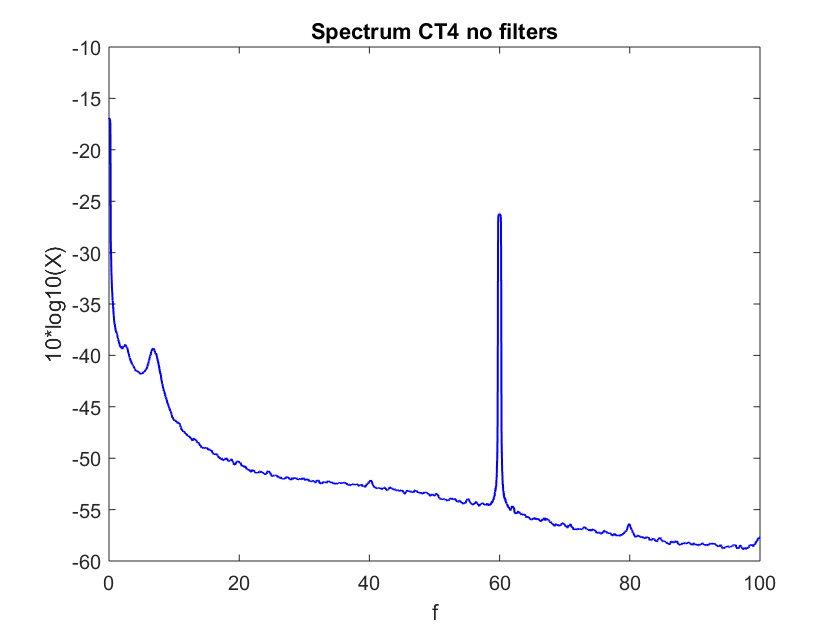

% Plot spectrum and spectrogram to look for artifacts
plot_spectrum_seg(CT2, 20, params); title('Spectrum CT4 no filters')

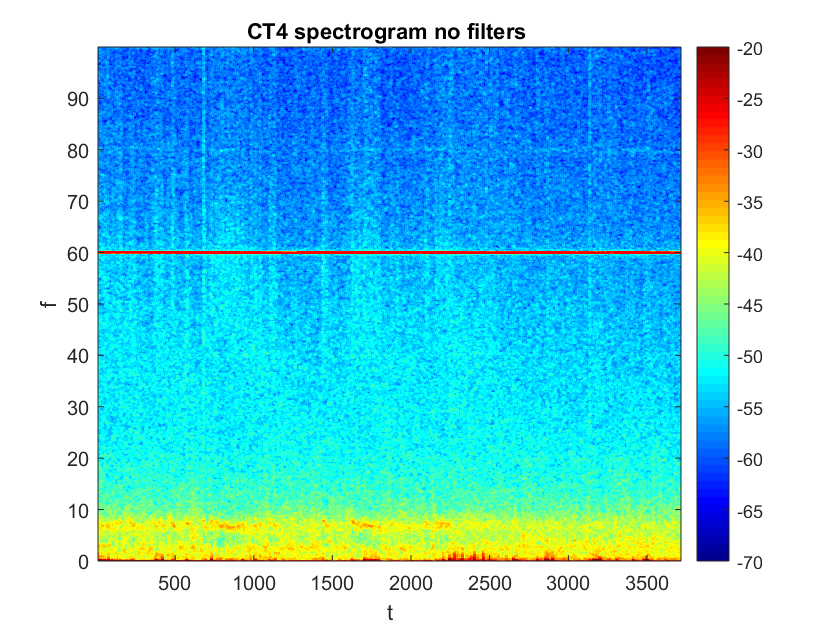


plot_spectrogram(CT2, [20 1], params) ; title('CT4 spectrogram no filters ');

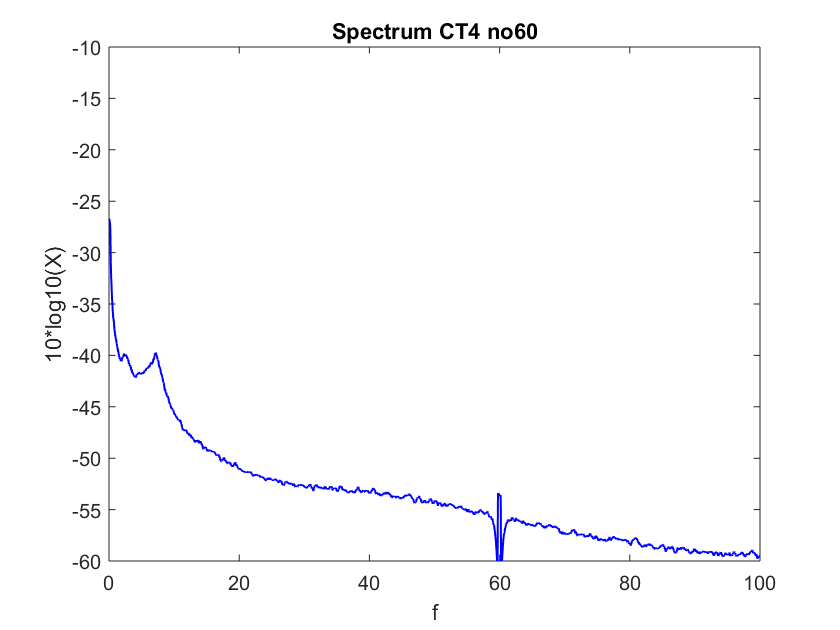


    % Only see 60 Hz noise, no artifacts

% Remove 60 Hz noise 
alpha = 0.997; 
band = 60;
F_CT2 = remove60(CT1, params.Fs, alpha, band);

% Plot with Filter
plot_spectrum_seg(F_CT2, 20, params); title('Spectrum CT4 no60');

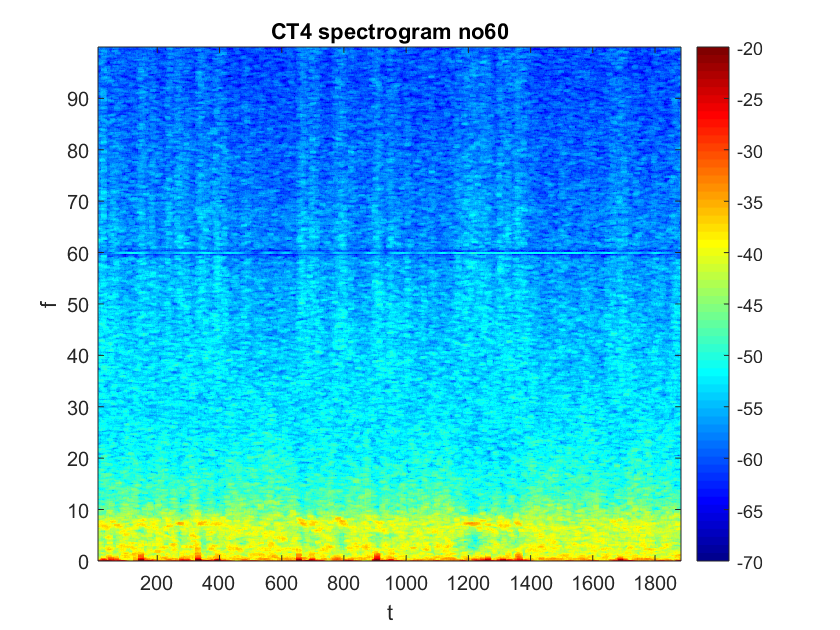


plot_spectrogram(F_CT2, [20 1], params) ; title('CT4 spectrogram no60');

## CT1 low pass test

% Plot spectrum and spectrogram to look for artifacts
plot_spectrum_seg(CT1, 20, params); title('Spectrum CT1 no filters')


plot_spectrogram(CT1, [20 1], params) ; title('CT1 spectrogram no filters ');


    % Only see 60 Hz noise, no artifacts

% Remove 60 Hz noise 
alpha = 0.995; 
band = 60;
F_CT1 = remove60(CT1, params.Fs, alpha, band);

% Plot with Filter
plot_spectrum_seg(F_CT1, 20, params); title('Spectrum CT1 no60');


plot_spectrogram(F_CT1, [20 1], params) ; title('CT1 spectrogram no60');


%%%%%%%%%%%%%%%%%%%%%%%

params.fpass = [5 100]

params = struct with fields:
        Fs: 1000
     fpass: [5 100]
       pad: 0
    tapers: [5 9]


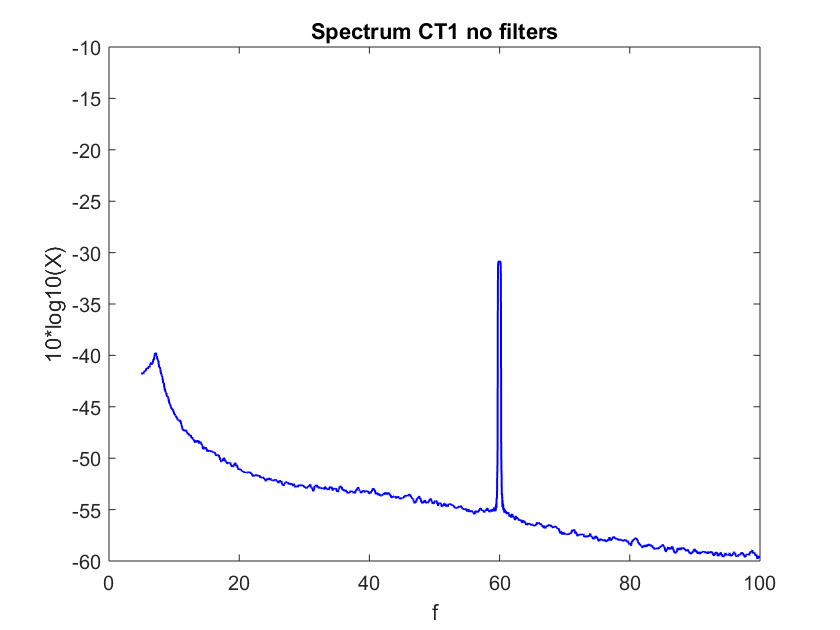


% Plot spectrum and spectrogram to look for artifacts
plot_spectrum_seg(CT1, 20, params); title('Spectrum CT1 no filters')

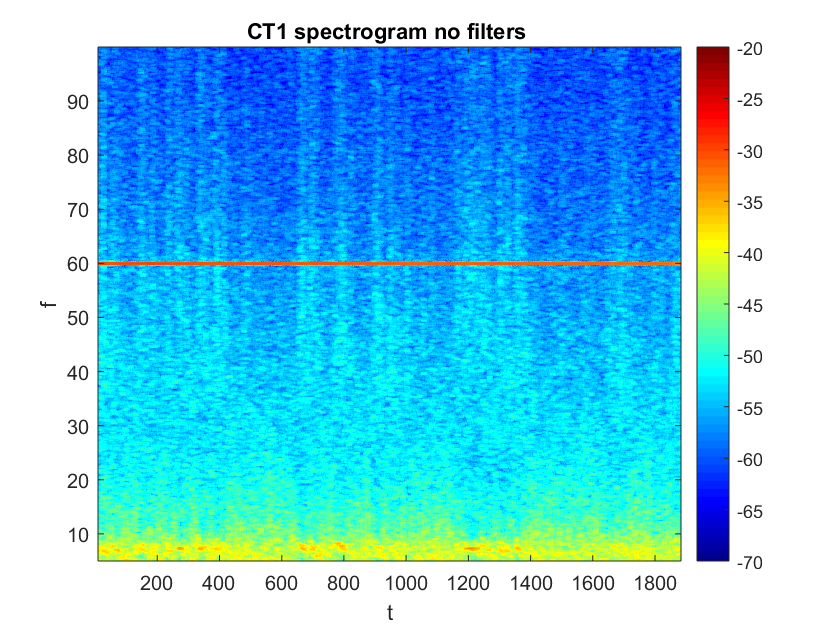


plot_spectrogram(CT1, [20 1], params) ; title('CT1 spectrogram no filters ');

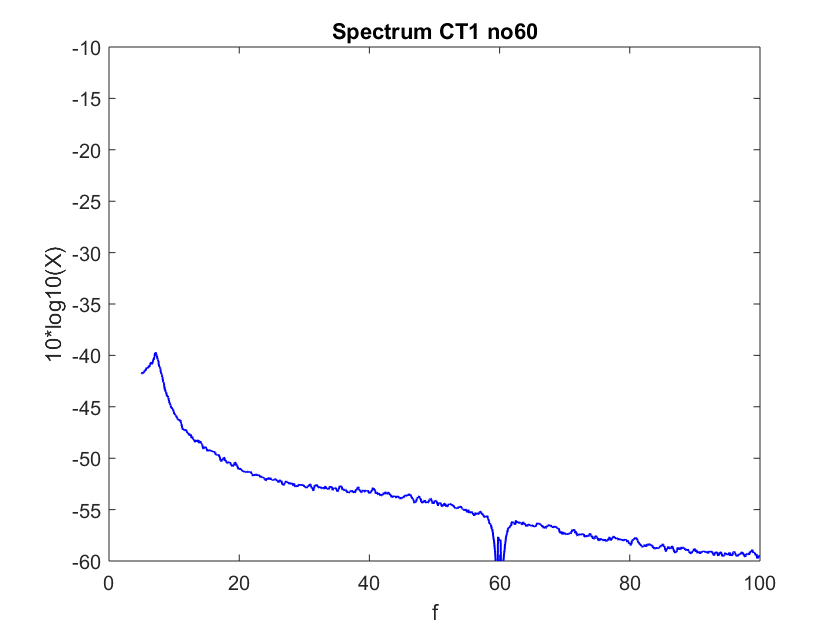


    % Only see 60 Hz noise, no artifacts

% Remove 60 Hz noise 
alpha = 0.995; 
band = 60;
F_CT1 = remove60(CT1, params.Fs, alpha, band);

% Plot with Filter
plot_spectrum_seg(F_CT1, 20, params); title('Spectrum CT1 no60');

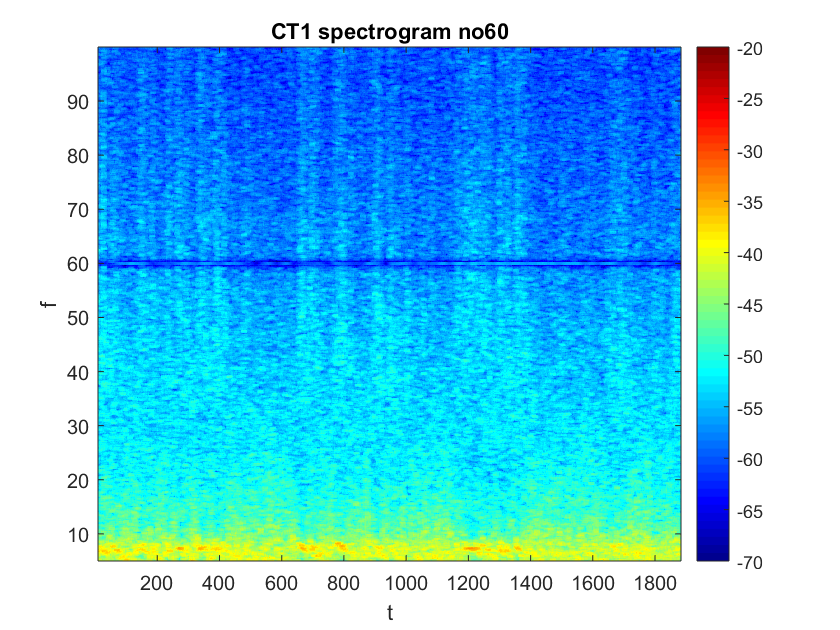


plot_spectrogram(F_CT1, [20 1], params) ; title('CT1 spectrogram no60');

# Functions

## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60_cells(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.9975;
omega = 2*pi*60/Fs;
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)))
end
result = cell_array
end

## Filter Band Noise from Array

function result = remove60(xarray, Fs, alpha, band)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

% alpha = 0.9975; Moved to function arguments
omega = 2*pi*band/Fs;
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2));

result = xarray;
end

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1}
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii})
end
result = x
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 ;
[S,f]=mtspectrumsegc(arrayx(:,2),window,params,segave);
figure; plot_vector(S,f); title('Spectrum log scale 10 second average window'); ylim([-60 -10]);
result = {S,f};
end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 -20])

end